# **一、从微分方程到状态观测器**

### ***1.什么是状态空间？***

在《信号与系统》中，我们习惯用传递函数$H(s)$ 来描述系统。

 
$$$ \frac{Y(s)}{U(s)} = \frac{1}{s^2 + 2s + 1} $$$
 

这是一个黑盒模型：如果你给它输入 $U$，它吐出输出 $Y$。但盒子内部发生了什么？我们不知道。

状态空间 (State Space)是白盒模型。 它认为：系统之所以能动，是因为内部有一些“变量”在随时间变化。这些变量叫状态 (State)。

**以牛顿第二定律举例：** 

假设你推一个质量 $m=1$ 的滑块。力是输入 $u$，位置是输出 $y$。 根据牛顿第二定律公式：$$F = ma \Rightarrow u = \ddot{y}$$。我们可以选两个内部变量（状态）： 

- 位置：$x_1 = y$ 

- 速度：$x_2 = \dot{y}$

现在，我们把二阶微分方程$$u = \ddot{y}$$拆成两个一阶微分方程：

- 状态1的变化率（位置的导数）： $\dot{x}_1 = x_2$ （速度）

- 状态2的变化率（速度的导数）： $\dot{x}_2 = u/m = u$ （加速度）

把它写成矩阵形式：


$$ \left[ \begin{array}{c} \dot{x}_1 \\ \dot{x}_2 \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ 0 & 0 \end{array} \right] \left[ \begin{array}{c} x_1 \\ x_2 \end{array} \right] + \left[ \begin{array}{c} 0 \\ 1 \end{array} \right] u $$



$$ y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x_1 \\ x_2 \end{array} \right] $$


这就是状态空间的标准形式：

###  
$$$ \dot{x} = Ax + Bu $$$


###  
$$$ y = Cx + Du $$$


- **A (系统矩阵)**：描述系统内部状态如何互相影响（比如速度改变位置）。

- **B (输入矩阵)**：描述输入$$u$ $如何改变状态（力改变速度）。

- **C (输出矩阵)**：描述我们能用传感器看到什么（只能看到位置 $x_1$）。

- **D (前馈矩阵)**：描述输入$$u$ $是否能**瞬间**直接改变输出$ $y$$。

在机器人位置/速度控制中，由于存在物理惯性，输入电压无法让位置/速度瞬间突变，因此通常$ $D = 0$$，此类系统称为严格真系统(Strictly Proper System)。

只有在测量加速度或纯电路系统中（输入量对于输出量没有积分环节 是纯增益系统/直接耦合系统），$$D$ $才可能不为 0。

### *2.为什么需要观测器？(Observer)*

在机器人控制中，我们经常遇到一个尴尬的局面：

- 我们需要什么：为了控制得稳，我们需要全状态反馈，也就是既要知道位置 $x_1$，也要知道速度 $x_2$。

- 我们有什么：为了省钱或空间，我们只有位置传感器（编码器），也就是我们只知道 $y=x_1$。

**对位置直接求导来得到速度有什么问题呢？**

     $v = (y_{new} - y_{old}) / \Delta t$。 

在工程中，微分会极大地放大噪声。如果位置传感器信息产生抖动，算出来的速度会极其吓人。

为了解决上述问题，我们引入观测器 (Observer)：一个基于数学的系统模型。还是以电机速度为例，我们的观测器进行以下两个步骤：

- 预测：观测器根据刚才的 $A, B$ 矩阵，预测电机位置

- 校正：将计算得到的预测位置和真实传感器位置进行。 如果不一样，那么根据这个误差，按比例修正观测器的猜测。

# **二、观测器的数学原理**

### ***1.观测器方程***

设 $\hat{x}$ (”你头顶怎么尖尖的“) 为我们估计的状态，观测器方程如下：

###  
$$$ \dot{\hat{x}} = \underbrace{A\hat{x} + Bu}_{\text{纯模型推算}} + \underbrace{L(y - C\hat{x})}_{\text{误差校正项}} $$$


### 
$$$ \dot{\hat{x}} = {(A-LC)\hat{x} + Bu} + {Ly}$$


- $y$：真实测到的位置

- $C\hat{x}$：我们要估计的位置

- $(y - C\hat{x})$：估计误差

- $$L$$：观测器增益矩阵

$L$ 越大：越相信传感器，校正越快，但噪声越大。 

$L$ 越小：越相信模型，越平滑，但如果模型不准，误差会很大。

*可以看出，这类观测器采用了模型预测 + 输出误差反馈的标准形式。其中L根据人为指定的观测器收敛速度计算得到（事实上我们只需要找到能使A-LC特征值小于0的l1与l2就可以达到收敛），具有这种设计思路的观测器我们称之为****龙伯格观测器(Luenberger Observer)。****他还有一个孪生兄弟，根据噪声统计得到最优估计，那种观测器叫做卡尔曼滤波器(Kalman Filter)，*

### ***2.利用位置传感器观测速度***

让我们设计一个观测器，在只有“位置数据”的情况下，把“速度”找回来。

使用***极点配置法 (Pole Placemen*****t)** 来计算增益$ $L$$

clear; clc; close all;

% 1. 建立模型 (简单的旋转电机)
% x1 = 角度 (rad), x2 = 角速度 (rad/s)
% 物理参数
J = 0.01;   % 转动惯量
b = 0.1;    % 阻尼 (摩擦力)
K = 0.01;   % 力矩常数

% 矩阵定义
A = [0, 1; 
     0, -b/J]; % 系统矩阵：角度导数是速度，速度导数受阻尼影响
B = [0; 
     K/J];     % 输入矩阵：u 是电压，产生力矩
C = [1, 0];    % 输出矩阵：我们只能观测到 x1 (角度)
D = 0;

% 2. 离散化 (Discretize)
% 单片机是数字系统，我们把连续的微分方程变成差分方程
Fs = 1000;          % 采样频率 1000Hz
Ts = 1/Fs;          % 采样时间 0.001s
sys_c = ss(A, B, C, D);
sys_d = c2d(sys_c, Ts, 'zoh'); % 转换为离散系统
[Ad, Bd, Cd, Dd] = ssdata(sys_d);

% 3. 设计观测器增益 L (Pole Placement)
% 我们需要决定观测器收敛得有多快。
% 规则：观测器的极点应该比系统本身的极点快 2~5 倍。

system_poles = eig(Ad); % 看看系统原本有多快
disp('系统固有极点:'); disp(system_poles);

系统固有极点:
    1.0000
    0.9900




% 我们把观测器极点配置得更靠近原点 (在z域，越近原点收敛越快)
desired_poles = [0.9, 0.85]; 

% 计算增益 L
% place 函数是自动控制原理中计算反馈增益的神器 极点配置法
% 公式对应：eig(Ad - L*Cd) = desired_poles
L = place(Ad', Cd', desired_poles)'; 

disp('计算出的观测器增益 L:'); disp(L);

计算出的观测器增益 L:
    0.2400
   12.6746



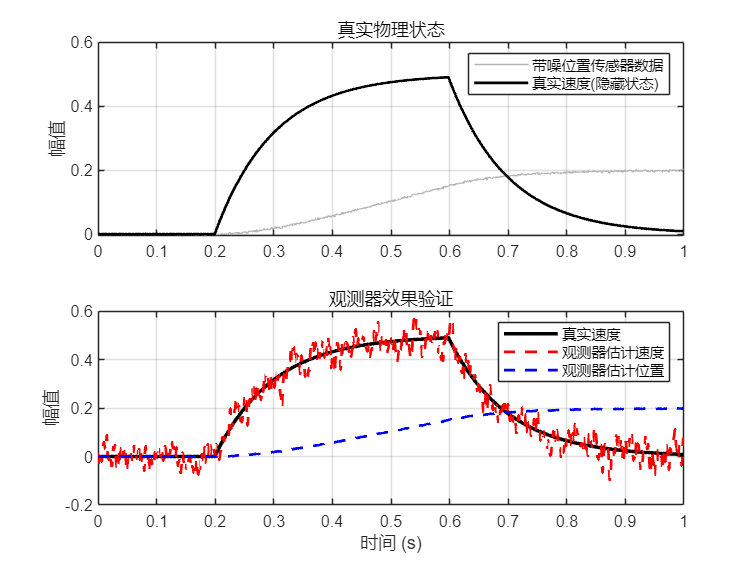

% 我们模拟 1 秒钟的过程
steps = 1000;
t = (0:steps-1) * Ts;

% 初始化
x_true = [0; 0];     % 真实状态 (上帝视角)
x_est  = [0; 0];     % 观测器估计状态 (你的算法视角)
u = 0;               % 输入电压

% 记录数据用于画图
history_v_true = zeros(1, steps);
history_x_est  = zeros(1, steps);
history_v_est  = zeros(1, steps);
history_pos    = zeros(1, steps);

for k = 1:steps
    % --- 生成输入信号 ---
    % 0.2秒时给一个 5V 电压，0.6秒时撤销
    if k > 200 && k < 600
        u = 5;
    else
        u = 0;
    end
    
    % --- 1. 模拟真实物理世界 (Plant) ---
    % 真实系统根据物理定律演变
    x_true = Ad * x_true + Bd * u;
    
    % 模拟传感器 (加一点点噪声！)
    % 这是观测器最厉害的地方：哪怕有噪声，也能算准
    noise = 0.002 * randn(); 
    y_sensor = Cd * x_true + noise; 
    
    % --- 2. 观测器算法 (Algorithm) ---
    % 这一步就是你会写进单片机 C 代码里的逻辑
    
    % Step A: 算出估计的传感器值
    y_est = Cd * x_est;
    
    % Step B: 算出误差
    error = y_sensor - y_est;
    
    % Step C: 更新估计状态 (预测 + 校正)
    x_est = Ad * x_est + Bd * u + L * error;
    
    % --- 3. 记录数据 ---
    history_v_true(k) = x_true(2); % 真实速度
    history_x_est(k)  = x_est(1);  % 估计位置 ？？
    history_v_est(k)  = x_est(2);  % 估计速度
    history_pos(k)    = y_sensor;  % 测量到的位置
end

figure('Color', 'w');

subplot(2,1,1);
plot(t, history_pos, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, history_v_true, 'k', 'LineWidth', 1.5);
title('真实物理状态');
legend('带噪位置传感器数据', '真实速度(隐藏状态)');
ylabel('幅值'); grid on;

subplot(2,1,2);
plot(t, history_v_true, 'k', 'LineWidth', 2); hold on;
plot(t, history_v_est, 'r--', 'LineWidth', 1.5);
plot(t, history_x_est, 'b--', 'LineWidth', 1.5);
title('观测器效果验证');
legend('真实速度', '观测器估计速度','观测器估计位置');
xlabel('时间 (s)'); ylabel('幅值');
grid on;

仔细观察第二张图： 1. 红色虚线（估计值）在 0.2 秒电机启动瞬间，迅速追上了黑色实线（真实值）。 2. 尽管传感器位置数据（第一张图的灰线）有噪声，但观测出来的速度非常平滑。

这就是观测器的魔力：利用物理模型 $A, B$ 和反馈矩阵 $L$，在只有位置传感器的情况下， “观察”出了原本看不见的速度。

# **三、观测器应用的深层剖析**

疑问是：传感器 $y$ 给的是位置，我的误差 $(y - \hat{y})$ 也是位置误差。 为什么这个“位置误差”能用来修正“速度”呢？

答案藏在矩阵 $A$ 和增益 $L$ 的耦合关系里。

### *1. 矩阵方程*

我们的观测器方程是向量形式： $$ \dot{\hat{x}} = A\hat{x} + Bu + L(y - C\hat{x}) $$

让我们把它拆成两个标量方程（假设 $x_1$ 是位置，$$x_2$$ 是速度）。

- 系统矩阵 $A = \left[ \begin{array}{cc} 0 & 1 \\ 0 & 0 \end{array} \right]$ （简化模型，忽略阻尼）

- 增益矩阵 $L = \left[ \begin{array}{c} l_1 \\ l_2 \end{array} \right]$ （注意 $L$ 有两个元素）

展开后的方程组如下：

方程 (1) 估计位置的变化率：


$$$ \dot{\hat{x}}_1 = \hat{x}_2 + l_1 \cdot (y - \hat{x}_1) $$$


方程 (2) 估计速度的变化率： 


$$$ \dot{\hat{x}}_2 = 0 + \frac{1}{J}u + l_2 \cdot (y - \hat{x}_1) $$$


 $\dot{\hat{x}}_2$ 是加速度（速度的导数）。$(y - \hat{x}_1)$ 是位置误差（真实位置 - 估计位置）。

*通过参数 *$l_1
$*，我们利用位置误差修正了对速度的估计*

*通过参数 *$l_2$*，我们利用位置误差修正了对加速度的估计*

### *2. 直观的物理逻辑推演*

想象一下，观测器（影子）正在追赶真实电机（真身）。

场景一：影子落后了

- 1.  现状：真实位置 $y = 100$，估计位置 $\hat{x}_1 = 90$。 

- 2.  误差：$$Error = 100 - 90 = 10$$ （正数）。

- 3.  对速度的修正（看方程2）：  $$ \dot{\hat{x}}_2 = \dots + l_2 \cdot 10 $$ 这相当于给影子的加速度猛踩了一脚油门！

- 4.  结果：影子的速度$\hat{x}_2$ 开始飙升。 

- 5.  连锁反应（看方程1）：速度 $\hat{x}_2$ 变快了，影子的位置 $\hat{x}_1$ 跑得更快，迅速追上真身。

场景二：影子跑超了

- 1.  现状：真实位置 $y = 100$，估计位置 $\hat{x}_1 = 110$。 

- 2.  误差：$$Error = -10$$ （负数）。 

- 3.  对速度的修正：  $$ \dot{\hat{x}}_2 = \dots + l_2 \cdot (-10) $$ 这相当于给影子的加速度踩了一脚刹车！ 

- 4.  结果：影子的速度 $\hat{x}_2$ 迅速下降，甚至变成负数（倒车）。 

- 5.  连锁反应：影子慢下来，等待真身追上来。

### *3. L矩阵的作用*

增益矩阵 $L = [l_1; l_2]$ 扮演了两个角色：

- $$l_1$$ (位置校正增益)： 直接把位置误差加到位置变化率上。作用是“拽”着影子往真身靠，类似于比例控制 (P)。

- $$l_2$ $(速度校正增益)：  这是最神奇的地方。它隐含了一个逻辑：  **“**如果我的位置猜错了，那一定是因为我刚才的速度猜错了。”所以，利用位置误差去修正速度是合理的。

这就是为什么观测器能算出速度：它利用位置误差的历史积累，不断反推并修正速度变量，直到位置误差归零时，速度也就自然对齐了。

### *4. MATLAB 验证：l2 对速度估计的影响*

让我们做一个小实验，把 l2 设为 0，看看还能不能估计出速度。

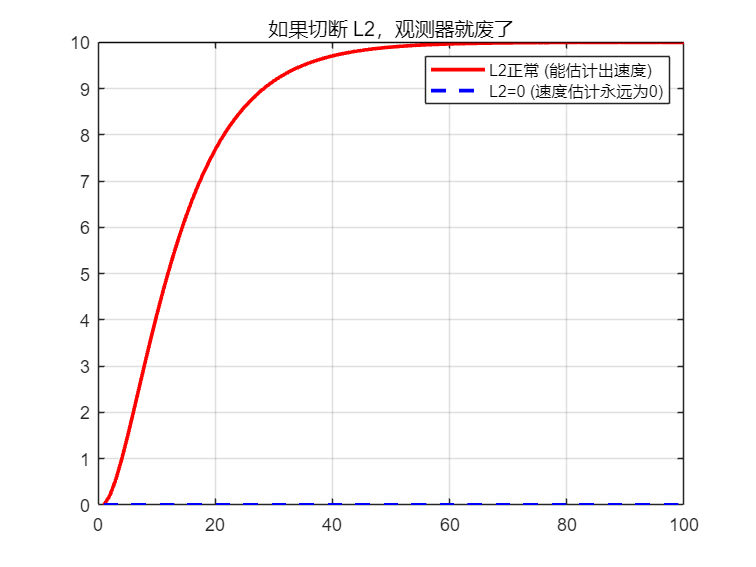

% 简单模型
A = [0 1; 0 0]; B = [0; 1]; C = [1 0]; D = 0;
Ts = 0.01;
sys = c2d(ss(A,B,C,D), Ts, 'zoh');
[Ad, Bd, Cd, Dd] = ssdata(sys);

% --- 实验 A: 正常的观测器 (L1, L2 都有值) ---
L_normal = place(Ad', Cd', [0.90, 0.80])'; 

% --- 实验 B: 只有位置校正，没有速度校正 (L2 = 0) ---
L_broken = L_normal; 
L_broken(2) = 0; % 强行切断速度修正通路！

% 仿真
steps = 100;
x_true = [0; 10]; % 真实电机在以 10 的速度匀速转动
x_est_A = [0; 0]; % 观测器A 从 0 开始猜
x_est_B = [0; 0]; % 观测器B 从 0 开始猜

log_v_A = [];
log_v_B = [];

for k = 1:steps
    y = Cd * x_true; % 测量位置
    
    % 更新真实状态
    x_true = Ad * x_true;
    
    % 更新观测器 A (正常)
    y_hat_A = Cd * x_est_A;
    x_est_A = Ad * x_est_A + L_normal * (y - y_hat_A);
    
    % 更新观测器 B (L2=0)
    y_hat_B = Cd * x_est_B;
    x_est_B = Ad * x_est_B + L_broken * (y - y_hat_B);
    
    log_v_A(end+1) = x_est_A(2);
    log_v_B(end+1) = x_est_B(2);
end

figure('Color', 'w');
plot(log_v_A, 'r', 'LineWidth', 2); hold on;
plot(log_v_B, 'b--', 'LineWidth', 2);
yline(10, 'k', '真实速度');
legend('L2正常 (能估计出速度)', 'L2=0 (速度估计永远为0)');
title('如果切断 L2，观测器就废了');
grid on;

### *5. 观测器位置估计 x1_hat 的价值*

本实验模拟一个低分辨率编码器，观察 x1_hat 如何消除“量化噪声”。

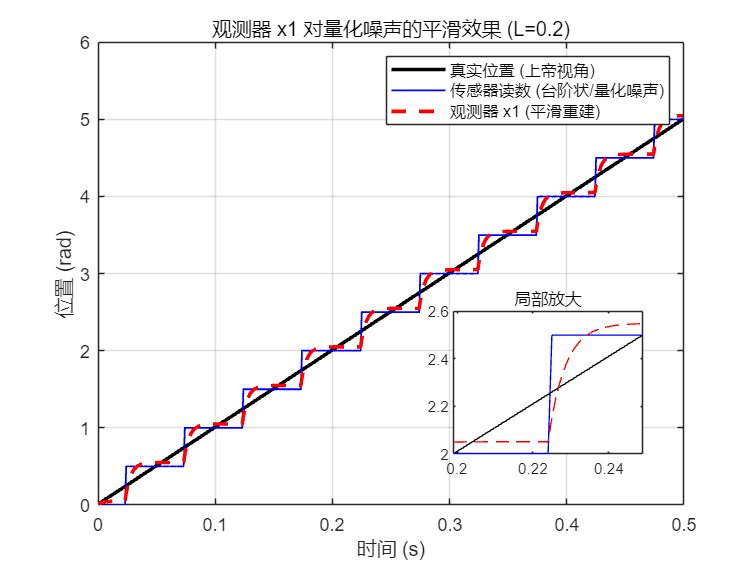

% --- 1. 系统定义 ---
% 简单一阶积分模型：速度 -> 位置
% x = [位置] (这里为了简单，假设我们直接控制速度，只观测位置)
A = 0; B = 1; C = 1; D = 0; 
Ts = 0.001; % 1ms
sys = c2d(ss(A,B,C,D), Ts, 'zoh');
[Ad, Bd, Cd, ~] = ssdata(sys);

% --- 2. 设计观测器 ---
% 极点配置在 0.8 (比较平滑)
L = place(Ad', Cd', 0.8)';

% --- 3. 仿真设置 ---
steps = 500;
t = (0:steps-1)*Ts;

x_true = 0;       % 真实位置 (浮点数，无限精度)
x_est = 0;        % 观测器估计位置
u = 10;           % 恒定速度输入 10 rad/s

% 模拟一个低分辨率编码器
% 假设分辨率是 0.5 rad (非常粗糙，为了让效果明显)
quantization_step = 0.5; 

log_pos_true = [];
log_pos_sensor = [];
log_pos_est = [];

for k = 1:steps
    % 1. 真实物理世界
    x_true = Ad * x_true + Bd * u;
    
    % 2. 糟糕的传感器 (加入量化效应)
    % round() 函数模拟了编码器的“取整”特性
    y_sensor = round(x_true / quantization_step) * quantization_step;
    
    % 3. 观测器更新
    y_hat = Cd * x_est;
    x_est = Ad * x_est + Bd * u + L * (y_sensor - y_hat);
    
    % 4. 记录
    log_pos_true(end+1) = x_true;
    log_pos_sensor(end+1) = y_sensor;
    log_pos_est(end+1) = x_est;
end

% --- 4. 绘图对比 ---
figure('Color', 'w');
plot(t, log_pos_true, 'k', 'LineWidth', 2); hold on;
plot(t, log_pos_sensor, 'b-', 'LineWidth', 1); 
plot(t, log_pos_est, 'r--', 'LineWidth', 2);

legend('真实位置 (上帝视角)', '传感器读数 (台阶状/量化噪声)', '观测器 x1 (平滑重建)');
title(['观测器 x1 对量化噪声的平滑效果 (L=' num2str(L) ')']);
xlabel('时间 (s)'); ylabel('位置 (rad)');
grid on;

% 画一个局部放大图
axes('Position',[.6 .2 .25 .25]);
box on; 
plot(t(200:250), log_pos_true(200:250), 'k'); hold on;
plot(t(200:250), log_pos_sensor(200:250), 'b-');
plot(t(200:250), log_pos_est(200:250), 'r--');
title('局部放大');

***使用***$ $\hat{x}_1$ $***替代位置传感器数据的优点***

    消除量化噪声 (Quantization Noise)：这是$ $\hat{x}_1$ $最直观的用处。

- 传感器痛点：真实的编码器是有分辨率的。比如 12位编码器，它读出来的数是“台阶状”的（0, 1, 1, 1, 2, 2...），不是连续的光滑曲线。

- $ $\hat{x}_1$ $ 的优势：因为模型是连续积分的，观测器算出来的$ $\hat{x}_1$ $是浮点数，它会平滑地切过这些台阶，还原出物体真实的运动轨迹。

    填补时间空隙 (Inter-sample Estimation)

- 场景：假设你的传感器只有 500Hz（2ms 更新一次），但你的控制回路跑在 1000Hz（1ms 一次）。

- 痛点：在传感器没更新的那 1ms 里，你该用什么位置做控制？如果沿用旧值，系统会顿挫。

- $ $\hat{x}_1$ $的优势：观测器每时每刻都在根据模型跑预测。在传感器还没发来新数据时，观测器已经算出了“这一毫秒”机器人应该在哪。这叫预测/插值。

    解决传输丢包/故障

- 场景：如果 CAN 总线拥堵，某一帧位置数据丢了。

- 痛点：直接用 $y$ 可能会读到 0 或者卡在上一帧不动。

- $ $\hat{x}_1$ $的优势：观测器具有惯性。即使这一帧没数据，它依然会根据之前的速度继续推演下一刻的位置。这极大地提高了系统的鲁棒性。

***使用***$ $\hat{x}_1$ $***替代位置传感器数据的代价***

    相位滞后 (Phase Lag)。

- 滤波器本质：观测器本质上是一个低通滤波器。凡是滤波，必有延迟。

- 后果：真实位置到了 100 度。$ $\hat{x}_1$ $可能才算到 99.5 度。这微小的滞后，在低频时没问题，但在高频高动态（比如电机急停急转）时，会导致相位裕度下降，系统变“软”，甚至震荡。

    工程法则：

- 如果你的观测器带宽配置得够高（$$L$ $比较大，响应快），$ $\hat{x}_1$ $ 的滞后可以忽略不计，推荐使用$ $\hat{x}_1$ $做反馈。

- 如果你追求极致的刚性（响应极快），或者观测器调得比较慢，建议用原始数据$ $y$ $做位置环反馈，只用 $ $\hat{x}_2$ $ 做速度环反馈。

***笔者：卢俊烨***

#### ***日期：2025.12.02***

***https://github.com/yagami-light7***